Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 100;              % Length of signal
t = (-L/2:L/2-1)*T;        % Time vector



x1 = sin(2*pi*50*t);
disp('x1(t) = sin(2*pi*50*t)')

x1(t) = sin(2*pi*50*t)


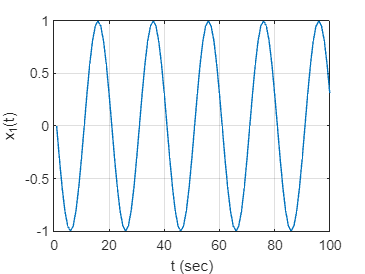

figure
plot(x1)
xlabel("t (sec)")
ylabel("x_{1}(t)")
grid on

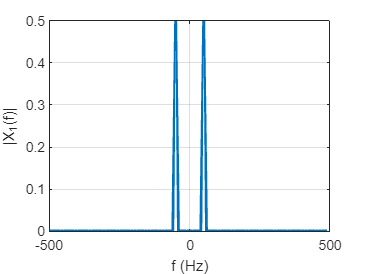

X = fft(x1);
X = X / length(x1);  % Normalizzazione
figure
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X)),"LineWidth",2)
xlabel("f (Hz)")
ylabel("|X_{1}(f)|")
grid on




% 100Hz
x2 = sinc(100*t);
disp('x2(t) = sinc(100*t)')

x2(t) = sinc(100*t)


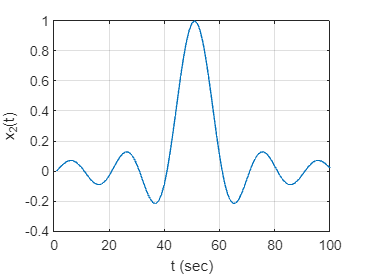

figure
plot(x2)
xlabel("t (sec)")
ylabel("x_{2}(t)")
grid on

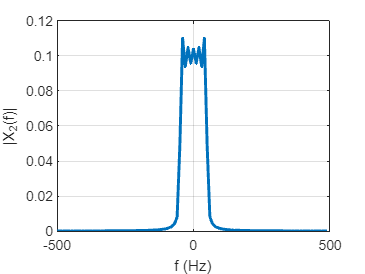

X = fft(x2) / length(x2);
figure
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X)),"LineWidth",2)
xlabel("f (Hz)")
ylabel("|X_{2}(f)|")
grid on




% 300 Hz
x3 = sinc(300*t);
disp('x3(t) = sinc(300*t)')

x3(t) = sinc(300*t)


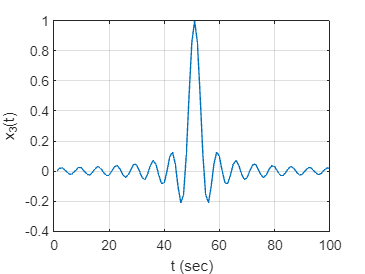

figure
plot(x3)
xlabel("t (sec)")
ylabel("x_{3}(t)")
grid on

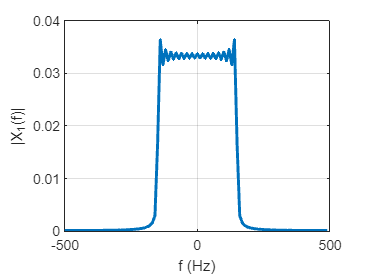

X = fft(x3) / length(x3);
figure
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(X)),"LineWidth",2)
xlabel("f (Hz)")
ylabel("|X_{1}(f)|")
grid on